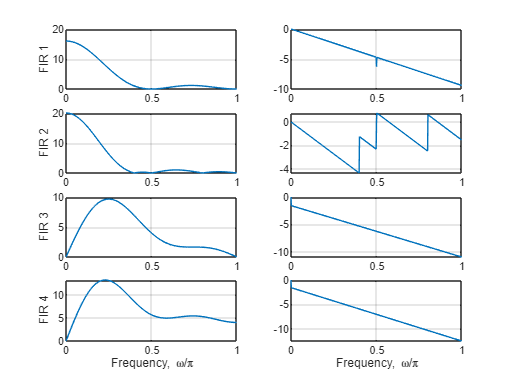

h1=[1 2 3 4 3 2 1]; % FIR 1 odd symmetry
h2=[1 2 3 4 4 3 2 1]; % FIR 2 even symmetry
h3=[-1 -2 -3 0 3 2 1]; %FIR 3 odd anti symmentric 
h4=[-1 -2 -3 -4 4 3 2 1] ; % FIR 4 even anti symmetric
w=0:0.01:pi;
[H1, w]=freqz(h1, 1, 512); 
[H2, w]=freqz(h2, 1, 512);
[H3 ,w]=freqz(h3, 1, 512);
[H4, w]=freqz(h4, 1, 512);
% Plot the magnitude and phase responses
% in angular frequency from 0 to pi
subplot(421); plot(w/pi, abs(H1));grid; ylabel('FIR 1')
subplot(422); plot(w/pi, unwrap(angle(H1)));grid;
subplot(423); plot(w/pi, abs(H2));grid; ylabel('FIR 2')
subplot(424); plot(w/pi, unwrap(angle(H2)));grid;
subplot(425); plot(w/pi, abs(H3));grid; ylabel('FIR 3')
subplot(426); plot(w/pi, unwrap(angle(H3)));grid;
subplot(427); plot(w/pi, abs(H4));grid
xlabel('Frequency, \omega/\pi'); ylabel('FIR 4')
subplot(428); plot(w/pi, unwrap(angle(H4)));
grid on;
xlabel('Frequency, \omega/\pi');

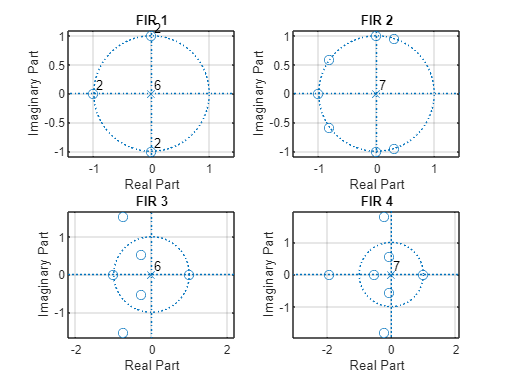

%Plot the zero - pole plots
figure
subplot(2,2,1)
zplane(h1,1); grid
title('FIR 1')
subplot(2,2,2)
zplane(h2,1);grid
title('FIR 2')
subplot(2,2,3)
zplane(h3,1);grid
title('FIR 3')
subplot(2,2,4)
zplane(h4,1);grid
title('FIR 4')

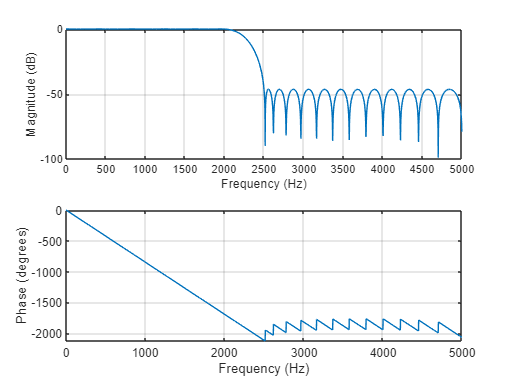

%2a
[N, Fo, Ao, W] = firpmord([2000 2500], [1 0], [0.005 0.005], 10000);
%N = ceil(N);
b = firpm(N, Fo, Ao, W);
freqz(b, 1, 2048, 10000);

%2b
% case (i) sampling rate of 20kHz
[N1, Fo1, Ao1, W1] = firpmord([2000 2500], [1 0], [0.005 0.005], 20000);
%N1 = ceil(N1);
disp(['Filter order for case (i) (sampling rate of 20kHz) is: ' num2str(N1)])

Filter order for case (i) (sampling rate of 20kHz) is: 94



% case (ii) δp = 0.002 and δs = 0.002
[N2, Fo2, Ao2, W2] = firpmord([2000 2500], [1 0], [0.002 0.002], 10000);
%N2 = ceil(N2);
disp(['Filter order for case (ii) (δp = 0.002 and δs = 0.002) is: ' num2str(N2)])

Filter order for case (ii) (δp = 0.002 and δs = 0.002) is: 57



% case (iii) stopband edge=2.3kHz
[N3, Fo3, Ao3, W3] = firpmord([2000 2300], [1 0], [0.005 0.005], 10000);
%N3 = ceil(N3);
disp(['Filter order for case (iii) (stopband edge=2.3kHz) is: ' num2str(N3)])

Filter order for case (iii) (stopband edge=2.3kHz) is: 78



%2c
[Nk, Wnk, beta, ft] = kaiserord([2000 2500], [1 0], [0.005 0.005], 10000);
Nk = ceil(Nk/2) * 2;
disp(['Filter order using firpmord is: ' num2str(N)])

Filter order using firpmord is: 47


disp(['Filter order using kaiserord is: ' num2str(Nk)])

Filter order using kaiserord is: 54


%2d
fs = 12000;
f = [1.2 1.8 3.6 4.2] * 1000 / fs;
a = [0 1 0];
dev = [0.02 0.1 0.02];
[n,fo,ao,w] = firpmord(f,a,dev,fs);
disp(['the order of the filter = '])

the order of the filter = 


disp( n )

      260248



%2e
fs = 12000;
f = [1.2 1.8 3.6 4.2] * 1000 / fs;
a = [0 1 0];
dev = [0.02 0.1 0.02];
[n1,fo,ao,w] = firpmord(f,a,dev,fs);
[n,Wn,beta,ftype] = kaiserord(f,a,dev,fs);
disp(n)

      435121



disp('Comparison with previous answer:')

Comparison with previous answer:


disp(n1)

      260248



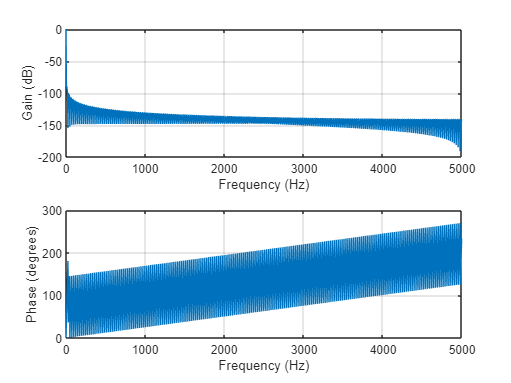

%2f
fs = 10000;
f = [2 2.5] * 1000 / fs;
a = [1 0];
dev = [0.005 0.005];
[n,fo,ao,w] = firpmord(f,a,dev,fs);
h = fir1(n, 2 * f(1) / fs, 'low');

[H,w] = freqz(h,1,1024,fs);
figure;
subplot(2,1,1);
plot(w,20*log10(abs(H)));
xlabel('Frequency (Hz)');
ylabel('Gain (dB)');
grid on;
subplot(2,1,2);
plot(w,unwrap(angle(H))*180/pi);
xlabel('Frequency (Hz)');
ylabel('Phase (degrees)');
grid on;

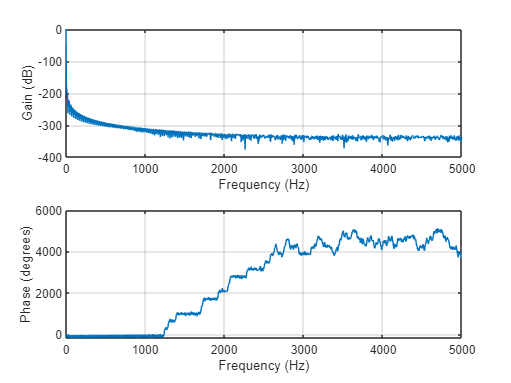

%2g
fs = 10000;
f = [2 2.5] * 1000 / fs;
a = [1 0];
dev = [0.005 0.005];
[n,fo,ao,w] = firpmord(f,a,dev,fs);
h1 = fir1(n, 2 * f(1) / fs, 'low', window(@blackman,n+1));

[H1,w] = freqz(h1,1,1024,fs);
figure;
subplot(2,1,1);
plot(w,20*log10(abs(H1)));
xlabel('Frequency (Hz)');
ylabel('Gain (dB)');
grid on;
subplot(2,1,2);
plot(w,unwrap(angle(H1))*180/pi);
xlabel('Frequency (Hz)');
ylabel('Phase (degrees)');
grid on;

%2h
fs = 10000;
f = [2 2.5] * 1000 / fs;
a = [1 0];
dev = [0.005 0.005];
h = firpm(firpmord(f,a,dev),f,a);

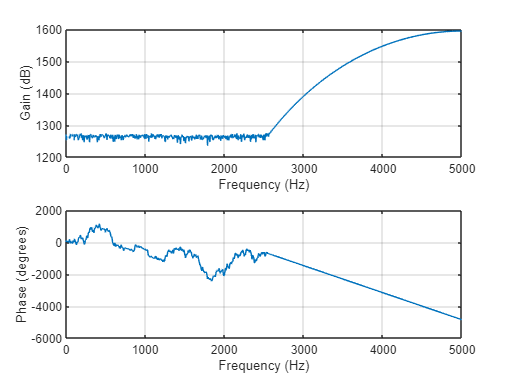


[H,w] = freqz(h,1,1024,fs);
figure;
subplot(2,1,1);
plot(w,20*log10(abs(H)));
xlabel('Frequency (Hz)');
ylabel('Gain (dB)');
grid on;
subplot(2,1,2);
plot(w,unwrap(angle(H))*180/pi);
xlabel('Frequency (Hz)');
ylabel('Phase (degrees)');
grid on;

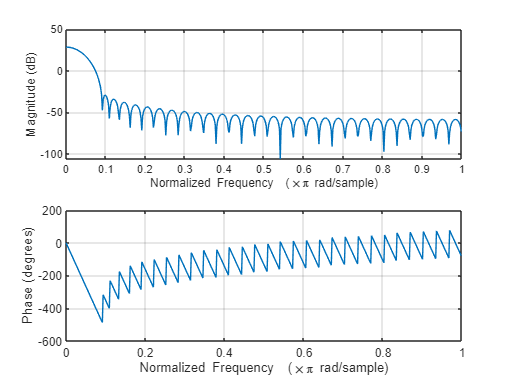


%2i
% Define the filter specifications
wp = 0.3*pi;
ws = 0.4*pi;
As = 50;

% Calculate the transition width and cutoff frequency
wt = ws - wp;
wc = (wp + ws) / 2;

% Calculate the filter length
N = ceil((As - 8) / (2.285 * wt));

% Determine the beta value based on the desired stop-band attenuation
beta = 7.95;

% Compute the Kaiser window
w = kaiser(N + 1, beta);



figure;
freqz(w);

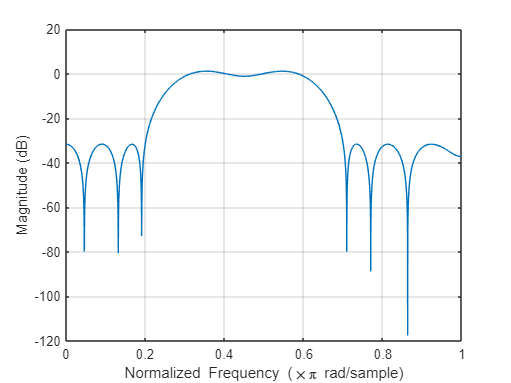


%2j
[N, Fo, Ao, W] = firpmord([1.2 1.8 3.6 4.2]*1e3, [0 1 0], [0.02 0.1 0.02], 12e3);
b = firpm(N, Fo, Ao, W);
[H, w] = freqz(b, 1, 2^12);
plot(w/pi, 20*log10(abs(H)));
xlabel('Normalized Frequency (\times\pi rad/sample)');
ylabel('Magnitude (dB)');
grid on;

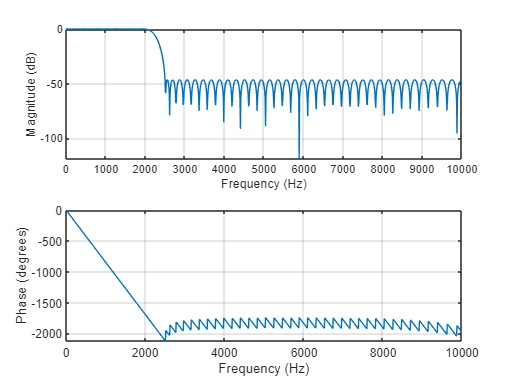

%2b
%case-1 when fs=20000
[N, Fo, Ao, W] = firpmord([2000 2500], [1 0], [0.005 0.005], 20000);
b = firpm(N, Fo, Ao, W);
freqz(b, 1,1024,20000);

disp(['filter length in case 1: ',num2str(N)]);

filter length in case 1: 94


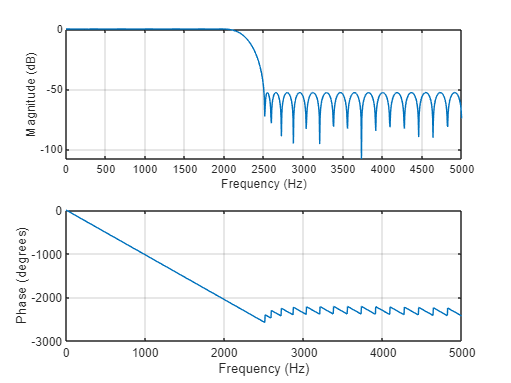

%2b
%case-2 when stop band and pass band ripple are 0.002
[N, Fo, Ao, W] = firpmord([2000 2500], [1 0], [0.002 0.002], 10000);
b = firpm(N, Fo, Ao, W);
freqz(b, 1,1024,10000);

disp(['filter length in case 2: ',num2str(N)]);

filter length in case 2: 57


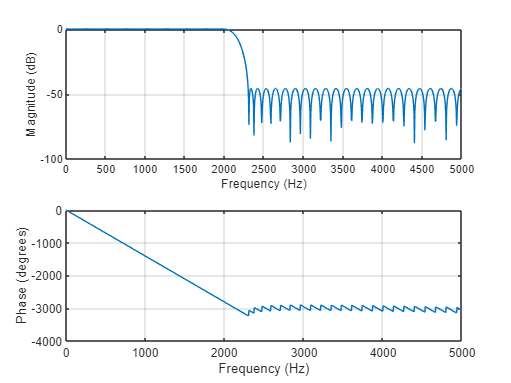

%2b
%case-3 when fstop =2.3k
[N, Fo, Ao, W] = firpmord([2000 2300], [1 0], [0.005 0.005], 10000);
b = firpm(N, Fo, Ao, W);
freqz(b, 1,1024,10000);

disp(['filter length in case 3: ',num2str(N)]);

filter length in case 3: 78


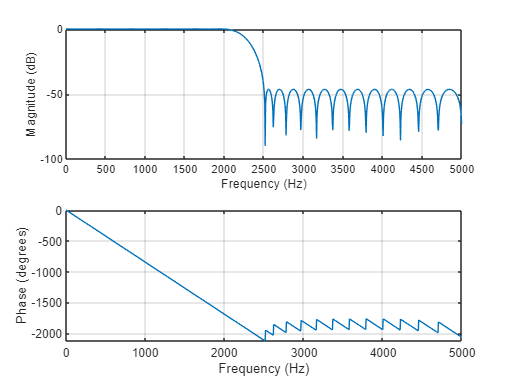

%2a
[N, Fo, Ao, W] = firpmord([2000 2500], [1 0], [0.005 0.005], 10000);
b = firpm(N, Fo, Ao, W);
freqz(b, 1, 1024, 10000);

%2c
[Nk, Wnk, beta, ft] = kaiserord([2000 2500], [1 0], [0.005 0.005], 10000);
disp(['Filter order using firpmord is: ' num2str(N)])

Filter order using firpmord is: 47


disp(['Filter order using kaiserord is: ' num2str(Nk)])

Filter order using kaiserord is: 54


%2d
fs = 12000;
f = [1.2 1.8 3.6 4.2] * 1000 / fs;
a = [0 1 0];
dev = [0.02 0.1 0.02];
[n,fo,ao,w] = firpmord(f,a,dev,fs);
disp(['the order of the filter = ',num2str(n)])

the order of the filter = 260248


%2e
fs = 12000;
f = [1.2 1.8 3.6 4.2] * 1000 / fs;
a = [0 1 0];
dev = [0.02 0.1 0.02];
[n1,fo,ao,w] = firpmord(f,a,dev,fs);
[n,Wn,beta,ftype] = kaiserord(f,a,dev,fs);
disp(['order of the filter in kaiser window: ',num2str(n)])

order of the filter in kaiser window: 435121


disp(['Comparison with previous answer:',num2str(n1)]);

Comparison with previous answer:260248


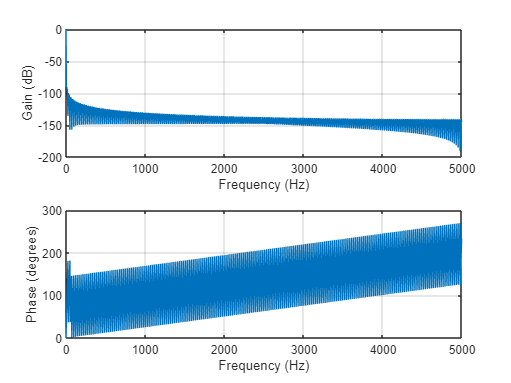

%2f
fs = 10000;
f = [2 2.5] * 1000 / fs;
a = [1 0];%low pass filter
dev = [0.005 0.005];
[n,fo,ao,w] = firpmord(f,a,dev,fs);
h = fir1(n, 2 *pi* (f(1) / fs), 'low');


[H,w] = freqz(h,1,1024,fs);
figure;
subplot(2,1,1);
plot(w,20*log10(abs(H)));
xlabel('Frequency (Hz)');
ylabel('Gain (dB)');
grid on;
subplot(2,1,2);
plot(w,unwrap(angle(H))*180/pi);
xlabel('Frequency (Hz)');
ylabel('Phase (degrees)');
grid on;

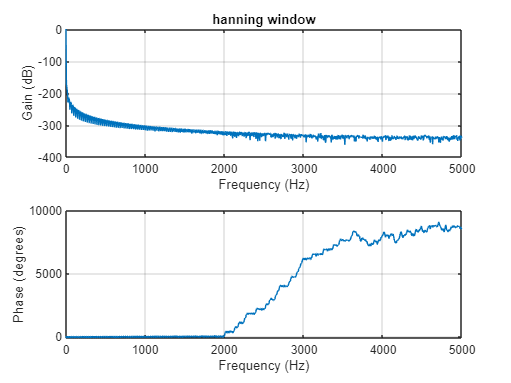

%2g hanning window
fs = 10000;
f = [2 2.5] * 1000 / fs;
a = [1 0];%low pass filter
dev = [0.005 0.005];
[n,fo,ao,w] = firpmord(f,a,dev,fs);
h = fir1(n, 2 *pi* (f(1) / fs),hanning(n+1));


[H,w] = freqz(h,1,1024,fs);
figure;
subplot(2,1,1);
plot(w,20*log10(abs(H)));
title('hanning window');
xlabel('Frequency (Hz)');
ylabel('Gain (dB)');
grid on;
subplot(2,1,2);
plot(w,unwrap(angle(H))*180/pi);
xlabel('Frequency (Hz)');
ylabel('Phase (degrees)');
grid on;

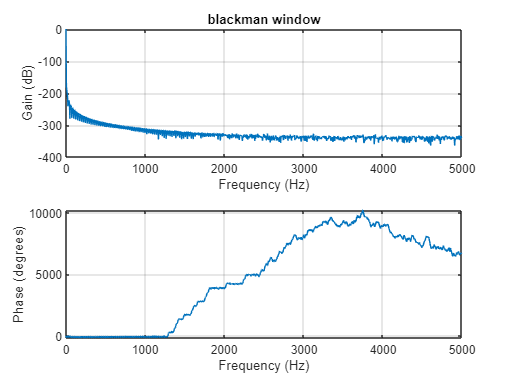


%2g blackman window
fs = 10000;
f = [2 2.5] * 1000 / fs;
a = [1 0];%low pass filter
dev = [0.005 0.005];
[n,fo,ao,w] = firpmord(f,a,dev,fs);
h = fir1(n, 2 *pi* (f(1) / fs),blackman(n+1));


[H,w] = freqz(h,1,1024,fs);
figure;
subplot(2,1,1);
plot(w,20*log10(abs(H)));
title('blackman window');
xlabel('Frequency (Hz)');
ylabel('Gain (dB)');
grid on;
subplot(2,1,2);
plot(w,unwrap(angle(H))*180/pi);
xlabel('Frequency (Hz)');
ylabel('Phase (degrees)');
grid on;

%2h 

fs = 10000;
f = [2 2.5] * 1000 / fs;
a = [1 0];
dev = [0.005 0.005];
h = firpm(firpmord(f,a,dev),f,a);


[H,w] = freqz(h,1,1024,fs);
figure;
subplot(2,1,1);
plot(w,20*log10(abs(H)));
xlabel('Frequency (Hz)');
ylabel('Gain (dB)');
grid on;
subplot(2,1,2);
plot(w,unwrap(angle(H))*180/pi);
xlabel('Frequency (Hz)');
ylabel('Phase (degrees)');
grid on;

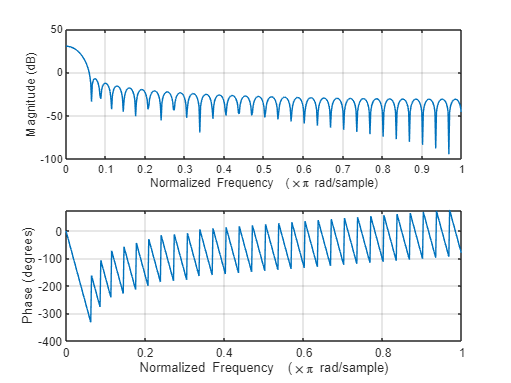

%2i
wp = 0.3*pi;
ws = 0.4*pi;
As = 50;

% Calculate the transition width and cutoff frequency
wt = ws - wp;
wc = (wp + ws) / 2;

% Calculate the filter length
N = ceil((As - 8) / (2.285 * wt));

% Determine the beta value based on the desired stop-band attenuation
%beta=0.5842(a-2.1)^0.4 +0.07886(A-21) for A=[21 50]
beta = 5.03;

% Compute the Kaiser window
w = kaiser(N + 1, beta);



figure;
freqz(w);

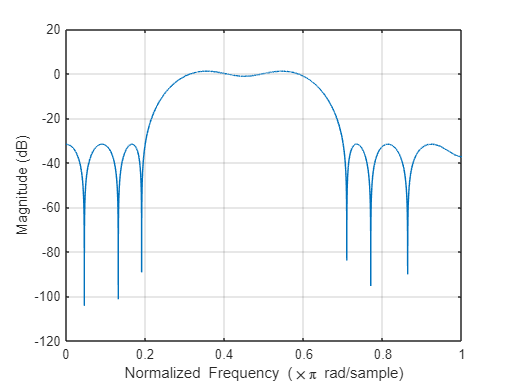

%2j
[N, Fo, Ao, W] = firpmord([1.2 1.8 3.6 4.2]*1000, [0 1 0], [0.02 0.1 0.02], 12000);
b = firpm(N, Fo, Ao, W);
[H, w] = freqz(b, 1, 12000);
plot(w/pi, 20*log10(abs(H)));
xlabel('Normalized Frequency (\times\pi rad/sample)');
ylabel('Magnitude (dB)');
grid on;

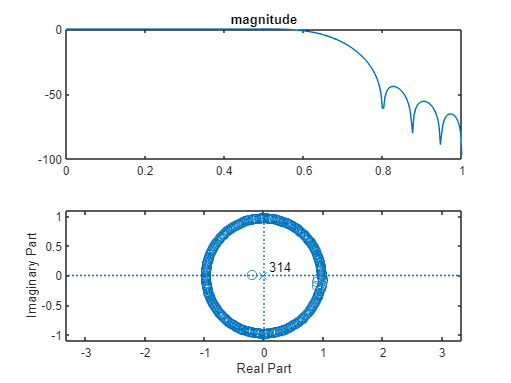

%fir filter using window method
n=23;%length of the sample
fc=200;
fs=600;
wc=2*pi*(fc/fs);
b=fir1(n,wc/pi,hanning(n+1));
w=0:0.01:pi;
h=freqz(b,1,w);
subplot(211);
plot(w/pi,20*log10(abs(h)));
title('magnitude');
subplot(212);
plot(w/pi,angle(h));
title('phase');
zplane(h);